# Relative Velocity

## 
$$v_A = v_B +v_{A/B}$$


## 
$$u_{A/B} = \omega*r$$


## 
$$v_{A/B} = \omega \times r     \rightarrow crossprodukt$$


## 
$$v_A = v_B +\omega \times r$$


# Opgave 5/48

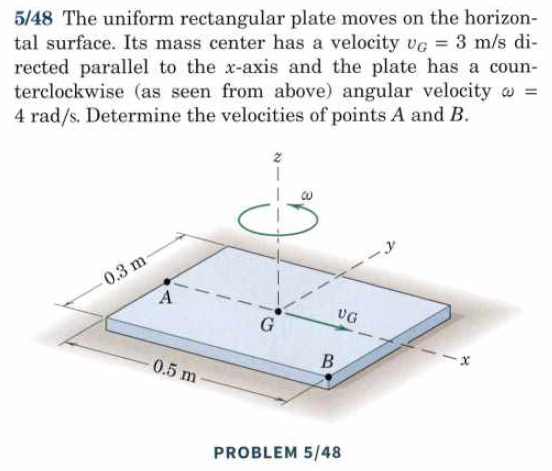

V_B = V_G

Omega = 4 rad/s

Vores vektorer for punkterne A & B er som følgende:

- A: [-0.25;0;0]

- B: [0.25;-0.15;0]

vg = [3;0;0];
vB = vg;

omega = [0;0;4];

A = [-0.25;0;0];
B = [0.25;-0.15;0];

V_a = vB + cross(omega,A)

V_a =      3
    -1
     0


V_b = vB + cross(omega,B)

V_b =     3.6000
    1.0000
         0


# Opgave 5/66

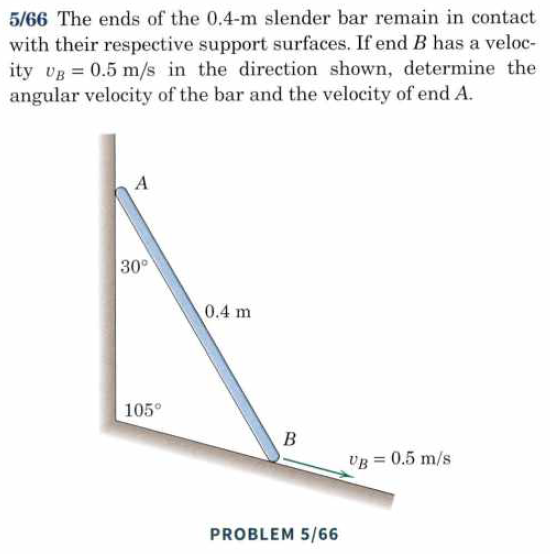

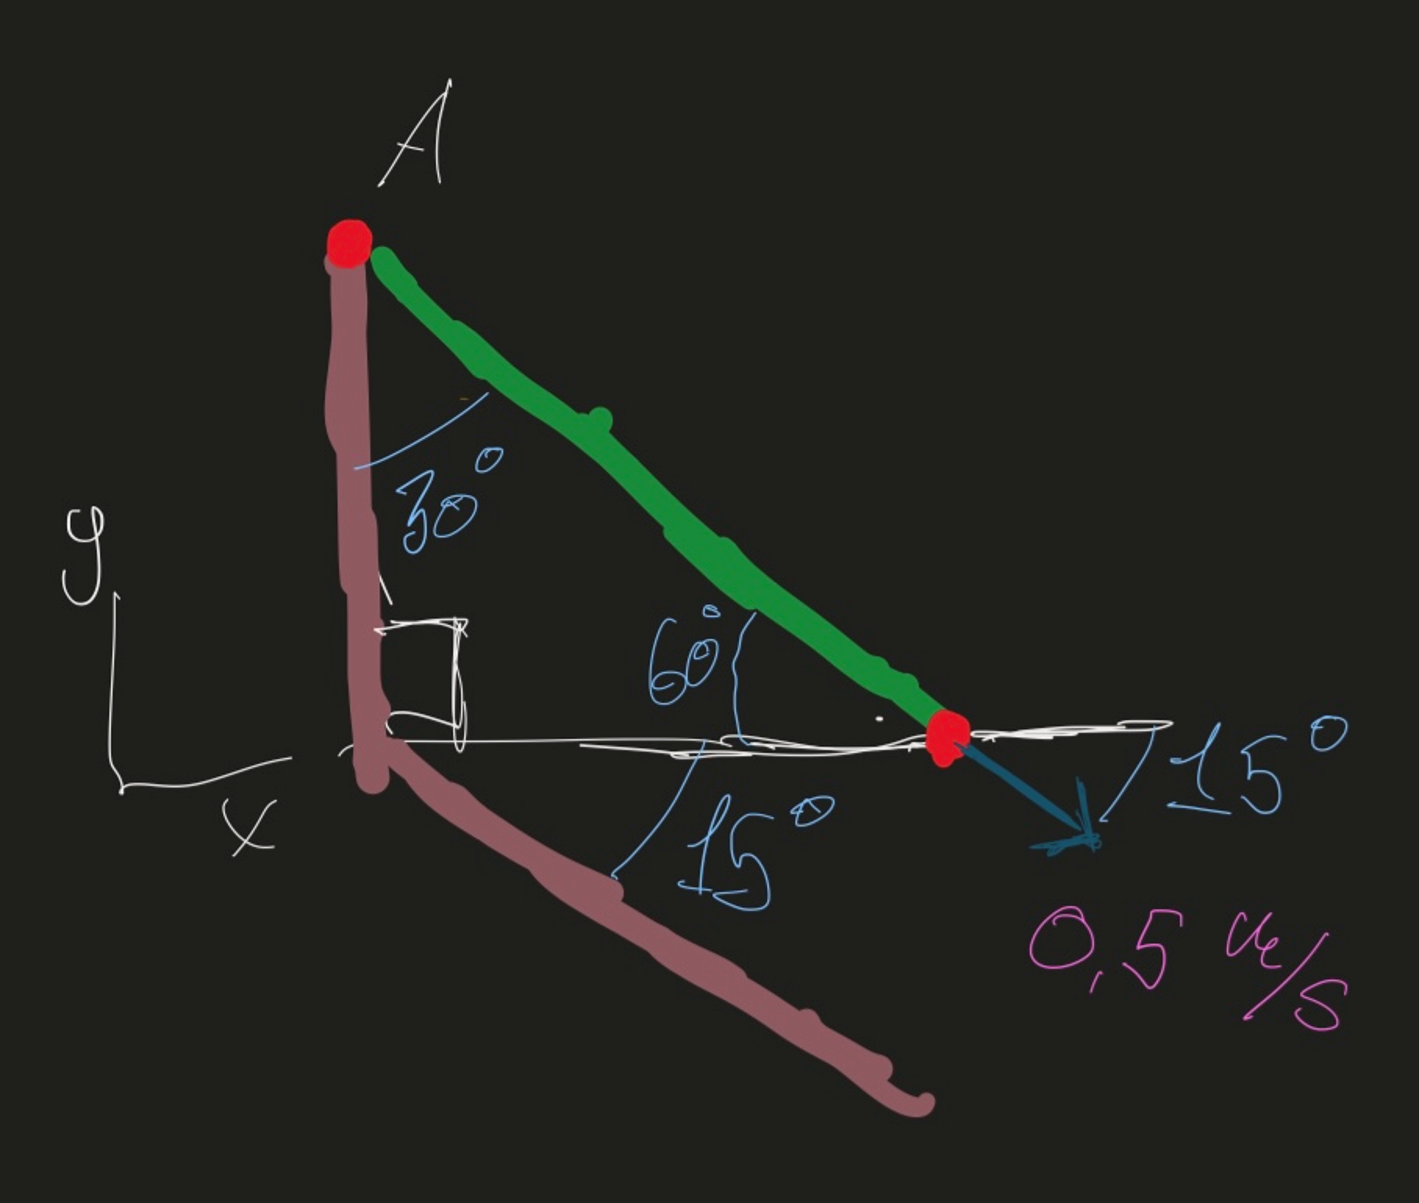

Vinkel A = 30°

Vinkel B = 105°

Vinkel C = 45°

a = (sin(30)*0.4m)/sin(105)

b = (sin(45)*0.4m)sin(105)

V_B = 0.5 m/s

Det ønskes at vi finder:

- Omega

- V_A

# Undervisning D. 28/11

- Vibration: Frie udæmpede svingninger

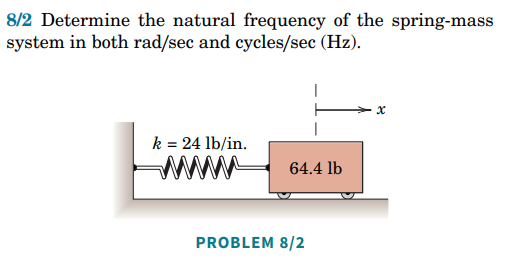

k = 4500 n/m

m = 20 kg

Bestem den naturlige frekvens i både rad/sec & Hz

u = symunit;
k = 4500;
m = 20;

omega = sqrt(k/m) 
ln    = omega/(2*pi)

omega = 15

ln = 2.3873

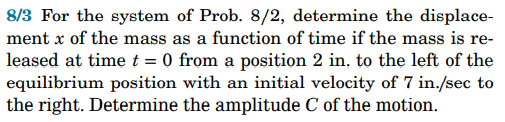

Informationer:


$$x(0) = -30 mm = x_0$$



$$\dot{x}(0) = 120 mm/s = v_0$$


Formlen, som vi skal anvende til at finde C, amplituden:


$$C = \sqrt{x_0^2 + (\dot{x_0}/\omega_n)^2}$$



$$\phi = arctan( (x_0*\omega_n)/\dot{x_0} )$$


x_0 = -30;
V_0 = 120;

C = vpa(sqrt(x_0^2 + (V_0/omega)^2))
Phi = vpa(atan((x_0 * omega)/V_0))

$$C = 31.048349392520047457724923534346$$

$$Phi = -1.3101939350475557688469052664004$$

t = linspace(0,3,300);
x = @(t) C * sin(omega*t - Phi);

plot(t,x(t))

Så bliver afstanden som funktion af tid: 


$$x(t) = 31.048 * sin(15 \frac{Rad}{Sec}*(t) - 1.31*Rad)$$


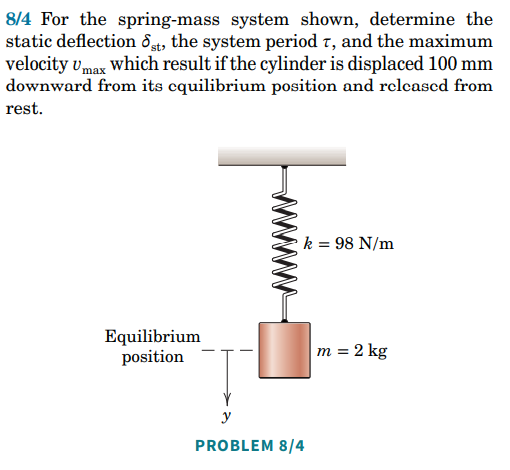

Informationer:


$$k = 98 N/m$$



$$m = 2 kg$$



$$x_0 = 100 mm$$


Formler:


$$C = \sqrt{A^2 + B^2} \rightarrow x_0 = A*cos(\omega_n * 0) + 0 \rightarrow A = x_0$$



$$C = 100$$



$$\sigma_{st} = \frac{Weight}{k} \rightarrow \frac{(m*g)}{k}$$



$$t = \frac{2*\pi}{\omega}$$



$$\omega_n = \sqrt(\frac{k}{m})$$


k = 98;
m = 2;

g = 9.81;

x_0 = 100
V_0 = 0


x_0 = 100

omega = sqrt(k/m)

V_0 = 0


C = sqrt(x_0^2+(V_0/omega)^2)

omega = 7


psi = atan(x_0*omega/V_0)

C = 100


Statisk_Deflektion = vpa(((m*g)/k),4)

psi = 1.5708


tid_mellem_amplitude = (2*pi)/omega

$$Statisk\_Deflektion = 0.2002$$


syms x(t)

tid_mellem_amplitude = 0.8976


x(t) = C * sin(omega*t + psi)

dxdt(t) = diff(x(t),t)

$$x(t) = 100\,\sin\left(7\,t+\frac{\pi }{2}\right)$$


fplot(dxdt) % Hastighedsgraf

$$dxdt(t) = 700\,\cos\left(7\,t+\frac{\pi }{2}\right)$$


tid_hvor_V_max = solve(x(t) == 0,t) % Tiden, hvor vi har den højeste hastighed


vpa(dxdt(tid_hvor_V_max),3) % Angiver Maksimale hastighed.

$$tid\_hvor\_V\_max = \frac{\pi }{14}$$

$$ans = -700.0$$

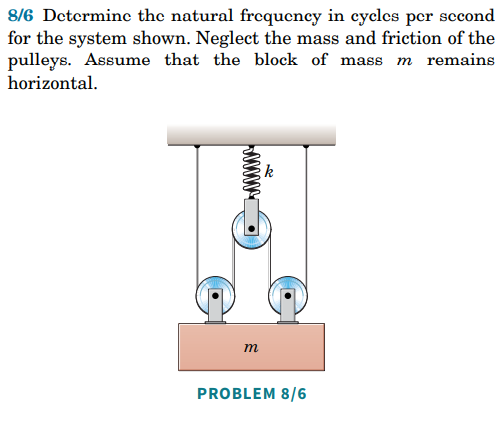

Tjek Brightspace.

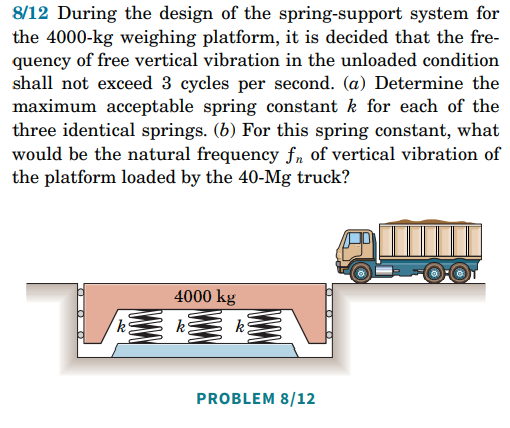

Informationer:

- Objekt:

- masse = 4000 kg

- Weight = 4000 kg * 9.81 m/s^2


$$k = 4000/3$$


m = 4000;
Lastbil = 40000;
hz = 3;
omega = (2*pi)/hz;

syms k
k_minimum = vpa(solve(hz == (1/(2*pi))*sqrt((3*k)/m),k),6)

frekvens = vpa((sqrt((3*k_minimum)/(m+Lastbil)))/(2*pi),3)

$$k\_minimum = 473741.0$$

$$frekvens = 0.905$$

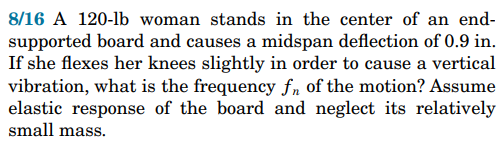

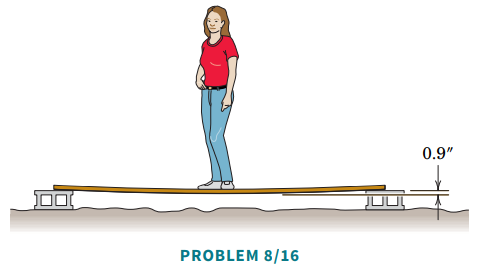

- Informationer

- Vægt: 120 Lbs = 55 kg

- Den statiske deflektion: 0.9 tommer = 2.286 cm -> 2.5 cm

Formler vi anvender:

- Den statiske deformation: $\sigma_{st} = \frac{m \cdot g}{k}$

- Omega: $\omega = \sqrt{\frac{k}{m}}$

- Frekvensen: $Hz = \frac{\omega}{2 \cdot \pi}$

clear
Mass = 55;
Deflation = 0.022;
Gravity = 9.81;

k = vpa((Mass * Gravity)/Deflation,6)
Omega = vpa(sqrt(k/Mass),6)
Hz = vpa(Omega/(2*pi),6)

$$k = 24525.0$$

$$Omega = 21.1166$$

$$Hz = 3.3608$$

## **Sample problem: 8/2**

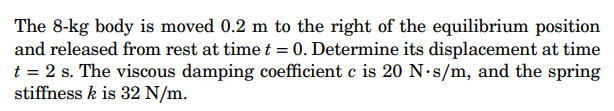

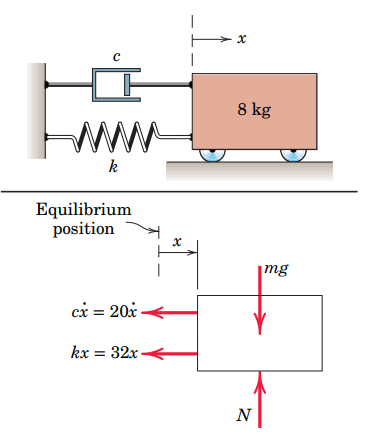

Informationer:

- Masse: m = 8 kg

- Fjeder koefficient: k = 20 N * sec/m

- Dæmpnings koefficienten: c = 20 N * s/m

Hvad ønsker vi at finde?:

- Den naturlige frekvens: $\omega_n 
$

- Dæmpning raten: $\zeta$

- Bestemmelse af $\zeta$ om den er under - lige på - eller over dæmpet.

- Den naturlige dæmpede frekvens: $\omega_d$

- Flytningen: x

- Hastigheden: $\dot{x}$

- Konstanten: C.

- Psi: $\psi$

clear;
m = 8;
k = 20;
c = 20;

omega_n = sqrt(k/m);
zeta_brug = 0;
zeta = c/(2*m*omega_n);
if zeta < 1
    zeta_brug = zeta
    display("SYSTEMET ER UNDER DÆMPET!");
elseif zeta == 1

zeta_brug = 0.7906

    "SYSTEMET ER UNDER DÆMPET!"



    zeta_brug = zeta
    display("SYSTEMET ER KRITISK DÆMPET!");
elseif zeta > 1
    zeta_brug = zeta
    display("SYSTEMET ER OVER DÆMPET!");
end



zeta = 0.7500

    "Systemet er under dæmpet"



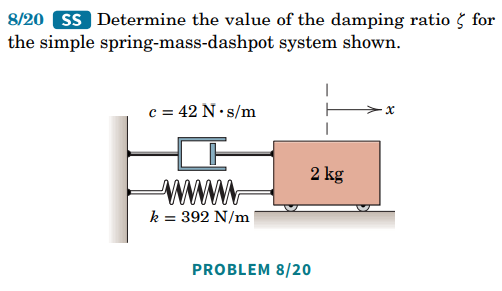

Informationer:

- Dæmpnings koefficient: c = 42 N * s/m

- Fjeder koefficient: k = 392 N/m

- Masse: m = 2 kg

Formler:

- Den naturlige frekvens: $\omega_n = \sqrt{\frac{k}{m}}$

- Dæmpningsforhold: $\zeta = \frac{c}{2 \cdot m \cdot \omega_n}$

c = 42;
k = 392;
m = 2;

omega_n = sqrt(k/m);
zeta = c/(2*m*omega_n)
display("Systemet er under dæmpet")